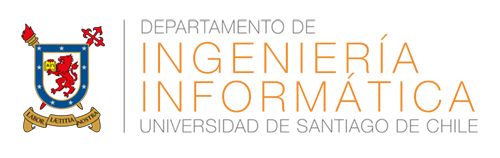

# Evaluación N° 2

## PROCESAMIENTO DE SEÑALES E IMÁGENES

Profesores:

- Violeta Chang C.

- Max Chacón.

Ayudante: Luis Corral

Estudiante: Valentina Paz Campos Olguin

# Generales

 Precaución al reproducir las señales, archivos wav o sus resultados en audífonos o altavoces ya que puede ocasionar daño a su sistema de reproducción o más importante a sus oídos. 

Entregue un archivo .mlx de Matlab sin ningún adjunto (archivos .wav, archivos .m ni otros). Se evalúa los conceptos y fórmulas en formato de texto, los comentarios dentro del código, la exactitud y simpleza del algoritmo y la calidad de los gráficos generados. Muestre solo los valores más importantes.

# Problema 1

El archivo 'ruido.wav' contiene una señal de voz $x[n]$ contaminada por tono puro de alta frecuencia. El archivo 'rifiltro.mat' (se carga con load('rifiltro.mat')) contiene la variable 'h' que es la respuesta al impulso $h[n]$ de un sistema (un filtro) para disminuir la contribución de la señal contaminante. Obtenga la señal de salida del sistema $y[n]$ cuando la entrada es la señal contaminada $x[n]$ a partir de su convolución (utilizando la función conv de matlab) con la respuesta impulso $x[n] * h[n]$ y utilizando la propiedad de la multiplicación $X[j\omega]  H[j\omega] $ en el dominio de la frecuencia (utilizando fft e ifft). Compare los tiempos de ejecución (utilizando la funcion timeit de matlab) entre la convolución y la propiedad de la multiplicación (el proceso completo incluye la fft e ifft de $x[n]$ y $h[n]$) y comente los resultados. Luego, verifique que ambas operaciones son equivalentes graficando la magnitud de la señal resultante en el dominio de la frecuencia $Y[j\omega] $.

**Respuesta:**

% Se limpian el entorno de variables
clearvars;

% Se carga la señal y la respuesta al impulso, respectivamente.
[y, Fs] = audioread('ruido.wav')

y =    -0.0011
    0.0018
    0.0006
   -0.0034
   -0.0060
   -0.0042
   -0.0006
    0.0002
   -0.0016
   -0.0038


Fs = 44100

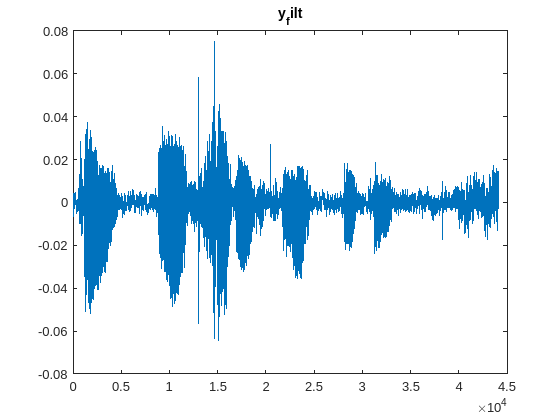


% Se carga h
load('rifiltro.mat')

% Se convoluciona la señal de entrada con la respuesta al impulso.
y_conv = conv(y, h);

% Se aplica la transformada rapida de Fourier en ambas señales, se multiplican
% y luego se aplica la transformada inversa de Fourier.
Y = fft(y);

% Se obtiene la longitud de la señal Y para que el resultado tenga
% la misma longitud  N que Y.
N = length(Y);

% Se calcula la FFT de la respuesta al impulso h pero asegurandose
% de que tengan la misma longitud.
H = fft(h, N);

% Se multiplica elemento a elemento las dos señales. Equivalente a
% convolucionar las dos señales en el dominio del tiempo.
Y_filt = Y .* H;

% Se aplica la transformada de Fourier inversa para volver al dominio del
% tiempo.
y_filt = ifft(Y_filt);

figure;
G = (0:length(y_filt) - 1) * (Fs/length(y_filt));
plot(G, y_filt);
title('y_filt');


% Se emplea la comparacion de tiempos de ejecucion de cada
% metodo.
time_conv = timeit(@() conv(y, h));
time_fft = timeit(@() ifft(fft(y) .* fft(h, length(y))));
fprintf('Tiempo de ejecución para la convolución: %f segundos\n', time_conv);

Tiempo de ejecución para la convolución: 0.330415 segundos


fprintf('Tiempo de ejecución para la FFT: %f segundos\n', time_fft);

Tiempo de ejecución para la FFT: 0.009055 segundos


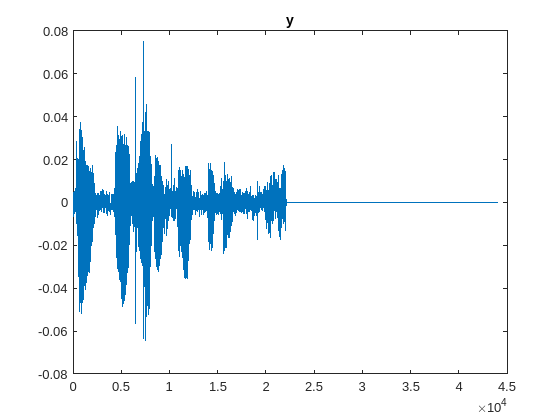

% Calcular la FFT es mucho mas rapida que realizar la convolucion.

% Se procede a comparar las señales resultantes de forma grafica

% Se calcula la FFT de la señal convolucionada.
Y_conv = fft(y_conv(1:length(y)));

% Se calcula la FFT de la señal filtrada en el dominio de la frecuencia.
Y_filt = fft(y_filt);

% Se construye el vector de frecuencias
f = (0:length(Y_conv) - 1) * (Fs/length(Y_conv));
F = (0:length(y_conv) - 1) * (Fs/length(y_conv));

figure;
plot(F, y_conv);
title('y');

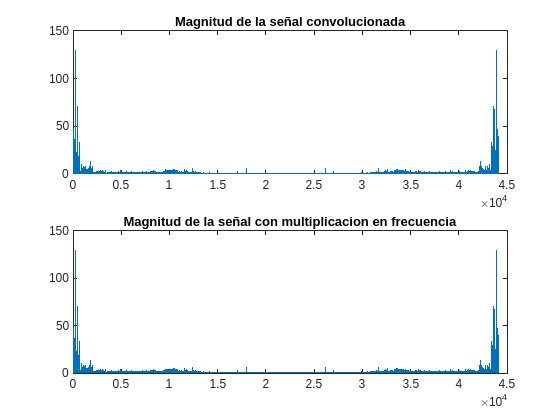


subplot(2, 1, 1);
plot(f, abs(Y_conv));
title('Magnitud de la señal convolucionada');

subplot(2, 1, 2);
plot(f, abs(Y_filt));
title('Magnitud de la señal con multiplicacion en frecuencia')


% De manera grafica se puede notar que ambas operaciones son equivalentes.
% La unica diferencia es el tiempo que tardan en ejecutarse, siendo la FFT
% la mas eficiente.

# Problema 2

El archivo 'senal.p' (Fs = senal();)es una función que genera una señal de frecuencia variable y luego retorna la frecuencia de muestreo Fs y un gráfico tiempo/frecuencia a partir de la transformada de wavelet de la señal. Describa el comportamiento temporal y espectral de la señal a partir del grafico generado.

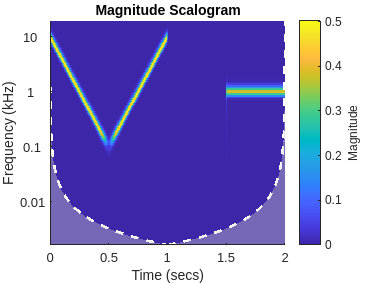

% Se limpia el entorno de variables
clearvars

Fs = senal();


% Comportamiento temporal
% - De 0 [s] a 1[s]:
% Se puede ver que desde los 0[s] hasta los 0.5[s], la frecuencia baja
% gradualmente desde los 10[kHz] hasta los 0.1[kHz].
% Luego, a partir de los 0.5[s] hasta los 1[s] sube gradualmente la
% frecuencia de la señal hasta 10[kHz], formando una V con una magnitud muy
% cercana a 0.5.

% - De 1.5[s] hasta 2[s]
% En este intervalo de tiempo se evidencia una franja horizontal con un
% grosor mas grande que el que forma la V, viendose ademas que tiene una
% magnitud mas baja que la presentada en la V.

% Comportamiento espectral
% Los colores, que van desde el morado hasta el amarillo, indican la
% intensidad de la transformada de wavelet. El morado indica las magnitudes
% bajas y el amarillo las magnitudes altas.


# Problema 3

Diseñe un filtro notch con frecuencia de corte $f_c = 5000 Hz$ posicionando un par conjugado de polos con radio $r = \sec(50 \pi/F_s) - \tan(50 \pi/F_s)$ y un par conjugado de ceros con $r = 1$, ambos de ángulo $\theta$ en la frecuencia de corte (escalando en radianes o grados según corresponda). Grafique el plano de polos-ceros y en una segunda figura la magnitud de la respuesta en frecuencia del filtro. Obtenga el valor de la frecuencia de muestreo $F_s$ para sus cálculos desde el archivo  'white_noise_263s_Matlab10_EDIT.wav' y aplique su filtro a los 3 primeros segundos utilizando la función filter. Verifique su resultado graficando la magnitud de la transformada rápida de Fourier de la señal original y la filtrada.

# Funciones

% Se limpia el entorno de variables
clearvars;

% Se lee la frecuencia dde muestreo del archivo de audio
[~, Fs] = audioread('white_noise_263s_Matlab10_EDIT.wav');

% Se definen los parametros del filtro notch
f_corte = 5000;
radio_polos = sec(50*pi/Fs) - tan(50*pi/Fs);
radio_ceros = 1;

% Se convierte la frecuencia de corte a radianes
theta = 2 * pi * f_corte/Fs

theta = 0.6545


% Se determina la ubicacion de polos y ceros
ceros = [1, -2 * radio_ceros * cos(theta), radio_ceros * radio_ceros];
polos = [1, -2 * radio_polos * cos(theta), radio_polos * radio_polos];

% Se grafica el plano de polos y ceros
figure;
zplane(ceros, polos);

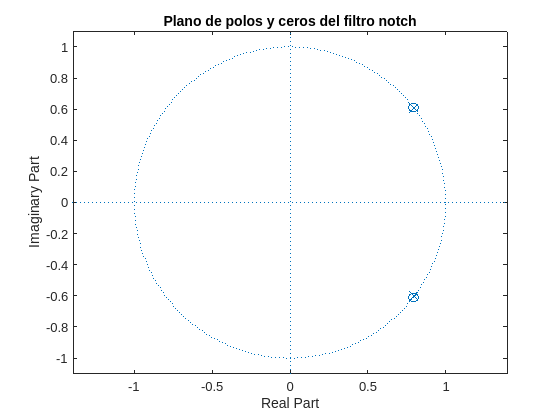

title('Plano de polos y ceros del filtro notch');

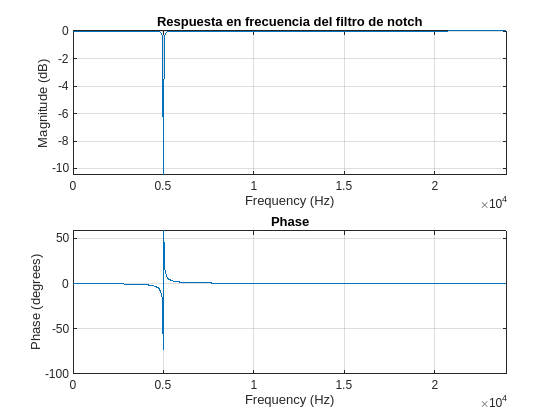


% Se grafica la magnitud de la respuesta en frecuencia
figure;
freqz(ceros, polos, 1024, Fs);
title('Respuesta en frecuencia del filtro de notch');

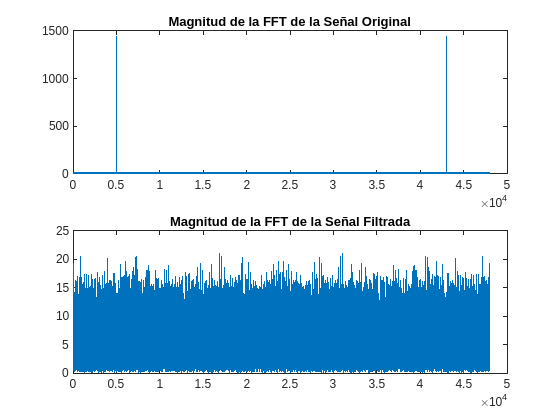


% Se leen los primeros 3 segundos de la señal
[y, Fs] = audioread('white_noise_263s_Matlab10_EDIT.wav', [1, 3*Fs]);

% Se aplica el filtro definido por los polinomios
y_filtrada = filter(ceros, polos, y);

% Se calcula la FFT de la señal original
Y = fft(y);

% Se calcula la FFT de la señal filtrada
Y_filtrada = fft(y_filtrada);

% Se construye el vector de frecuencias para el eje x del grafico de la FFT
f = (0:length(Y)-1)*(Fs/length(Y));

% Se grafica en 2 subplots la magnitud de la FFT de la señal y la señal
% filtrada.
figure;
subplot(2, 1, 1);
plot(f, abs(Y));
title('Magnitud de la FFT de la Señal Original');

subplot(2, 1, 2);
plot(f, abs(Y_filtrada));
title('Magnitud de la FFT de la Señal Filtrada');



%function timesvd(s)
%    svd(rand(s));
%end


%function timeeig(s)
%    eig(rand(s));
%end